# Exercise 2: Analysis of spontaneous activity 

version • 30May2024

**Goal: **Load and extract data from Spike2. Get spiketimes using a simple threshold. Analyze spontaneous activity.

## Experiment

The individual *Apteronotus* will be paralyzed by intramuscular curare injection. Curare blocks the neuromuscular junction, but since the electric organ is composed of modified axons in *Apteronotus*, its electric field is largely unaffected by the drug. The fish will be motionless, but will nevertheless be able to perform complex electrogenic behaviors.

Importantly, the fish will not be able to use its gills to respire, and therefore artificial respiration is necessary. Respiration is achieved by directing a flow of water into the fish’s mouth. Maintaining this flow is critical for the survival of the animal and for the success of the experiment. As much as we don’t like water in our lungs, these fish **DON’T** like air in their gills. If you see an air bubble, inform one of us immediately. 

We will continuously monitor the electric field of the fish on the oscilloscope - a sinusoidal-like waveform. This is the animal’s electric organ discharge (EOD), which is useful for monitoring the health of the fish and its behavior. Turn on the audio monitor to hear it - it should sound like a pure tone. 

Indeed, these animals expend a considerbable fraction of their metabolic budget producing this field: it is indeed a  good indicator of the overall health of the animal. 

***IT IS VERY IMPORTANT FOR YOU TO MONITOR THE EOD AMPLITUDE: IMMEDIATELY INFORM ONE OF US IF YOU SEE ANY SUDDEN DECREASE IN EOD AMPLITUDE.***  

NOTE: Fish are cold-blooded vertebrates; this means that their metabolic activity decreases with temperature and this includes the generation of their EOD. 

We use a recirculating flow of water - it is pumped from a bucket with a heater and a bubbler to the main tank. Overflow from the tank returns to the bucket. It’s important not to have the flow rate too high or too slow. 

## Recordings

- Pull  micropipettes using the Sutter puller and fill them with 3M KCl.

- Place the micropipette in the holder at the tip of the micropositioner. The electrode should be approximately vertical.

- Use the positioner to lower the electrode so that the tip is in the saline.

- Use the motor control to lower the electrode until you hit the surface of the brain

- Zero the depth monitor and begin to slowly lower the electrode in steps of 2 μm: don’t forget to buzz every once in a while. You should start seeing receptor afferents at about 900 μm (depending on where the electrode penetrated). Be patient, if you go too fast, the recordings will not be as stable.

Receptor afferents have high firing rates (150-500 spikes/sec) and are spontaneously active: make sure the signal-to-noise ratio (SNR) is large enough to trigger spikes reliably. Ask one of us if you’re not sure. Try recording baseline activity from a few units (50 seconds will be plenty). You should find plenty of receptors but holding the recording for more than 1-2 minutes is tough. Try buzzing again if the SNR gets too low, or try going up or down one step and buzzing again. 

# Exercise 3: Responses of central neurons

## Recordings

Depending on site, the summed activity of P cells should be registered on the recording electrode from about 500 μm on. P cells have low firing rates (5-50 spikes/sec), will typically show phase-locking to the search stimulus, and are also spontaneously active [make sure the signal-to-noise ratio is large enough to trigger spikes reliably for analysis]. To record from PCells:

- For central neurons, we may use pairs of *Wood's *metal electrodes  

- Use the motor control to slower lower the electrodes until you reach the surface of the brain

- Zero the depth monitor

- Gently lower the electrodes into the brain wile stimulating the animal with a global 4 Hz AM "search stimulus". Be patient, if the electrode is advanced too quickly, the tissue will be damaged and any recordings established will be less stable.

- Try recording baseline activity from a few PCell untis - about 1 minute each. If you used the search stimulus, be sure to let the activity recover (~ 1 min no stimulation) before recording baseline activity. 

NOTE: Remember to rinse the craniotomy with saline frequently between recordings!

## Stimulation

Once you have a stable recording, use deliver stimuli to the animal. The fish's EOD acts like a carrier signal - our stimuli are amplitude (and sometimes phase) modulations of the EOD. The relevant stimulus to the fish are the AMs. The fish has separate neural pathways for processing amplitude and phase modulations of the EOD: here we will be studying the pathway that codes for amplitude modulations exclusively. 

Stimulation can be applied through the buttons in the stimulation panel in Spike2. 

- Try recording PCell responses to sinusoidal AMs at 1, 2, 4, 8, 16, 32, 64, 128, 256 Hz. Each stimulus should be applied for at least 15-20 seconds. 

- Stimulation with random amplitude modulations (RAM). For this we prepared noise in the range of 0-120 Hz. 

- See how PCells respond to contrast modulated SAMs (this simulates what a fish might experience during an agonistic or courtship encounter). These are “envelopes” of the AM of the EOD (*i.e., an amplitude modulation of the amplitude modulation*) with different carrier frequencies (AM bandwidths)

- Adjust the stimulus intensity by varying the amplitude on the sine wave generator. A modulation depth of 15% is a typical stimulus contrast used in most studies.

# A) Basic Analysis of Neurophysiological data

## Pre-analysis for responses to central neurons

The afferent recordings are intracellular, and so we almost always record from a single unit. However, our other recordings are extracelullar, and therefore we may record from more than one neuron at a time. In those cases, we will use Spike2 to identify the individual neurons. There are tools in Spike2 that will group spikes belonging to individual PCells based on some spike characteristics (i.e., shape, amplitude, width,…). If you use Spike 2 to identify spikes, then we do not need to do the step "Extract spike times" below. Rather, we will use this command:

**spiketimes = ChX.times; where X is the appropriate channel exported from Spike2.**

## Load data 

This function opens your ".mat" exported from Spike2 and stores data from each channel into its own vector. In addition to the sampled data, the time vector for the stimulus channel is generated.

% load channel data
%[EODOXINGS, AM, AM_dt, vm, vm_dt, marker] = loadNSBdata;
uiopen('.mat');


% You may have to change the names of the variables to run this section.
% e.g. Ch2 = ELL_Envelopes_4_Ch2;

% Load the EOD zero crossings from channel 2
    EOD0Xings = Ch2.times; 

% Get the AM values
    AM = Ch3.values;

% set the sampling interval
    AMdT = Ch3.interval; 

% Create a time vector for the AM stimulus
    AMtime = AMdT:AMdT:length(AM)*AMdT;

% Get the membrane potential values
    Vm = Ch5.values;

% Set the sampling interval
    VmdT = Ch5.interval;
        vFs = 1/VmdT; % The samplerate

% Make a time sequence for the physiology data
    Vmtime = 1/vFs:1/vFs:length(Vm)/vFs;

% Get the dipole channel values
    dipole = Ch6.interval;

% Set the sampling interval of the dipole
    dipoledT = Ch6.interval;

% Get the start points of stimuli
    marker = Ch31.times;

clear Ch*

## Extract spike times from the membrane potential • Step 1: Filter

NOTE: If you extract the spike times before you export from Spike2, you do not need to run this section of code and should skip to the characterization of baseline activity. 

You’ve probably noticed that the membrane potential fluctuates a bit during the recordings. We can reduce this problem by high-pass filtering the trace. We compare the filtered and unfiltered traces below.

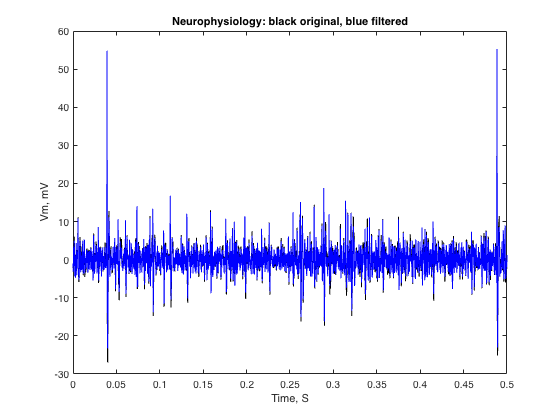

windowidth = 0.5; % Set this higher or lower if there are too few or too many spikes in the plot below.

vFs = 1/VmdT; % The samplerate
% Make a time sequence for the data
    tim = 1/vFs:1/vFs:length(Vm)/vFs;

% Plot unfiltered and filtered Vm traces
% Create a Butterworth filter with 200 Hz cutoff
    [B, A] = butter(2, 200/(vFs/2), 'high');
% Tilter the membrane potential
    vmfilt = filtfilt(B, A, Vm); 
% Plot the data
    figure; hold on; box on;
    plot(VmdT * (1:1:length(Vm)), Vm, 'k')
    plot(VmdT * (1:1:length(Vm)), vmfilt, 'b');
    xlim([0, windowidth])
    xlabel('Time, S')
    ylabel('Vm, mV')
    title('Neurophysiology: black original, blue filtered')

## Extract spike times from the membrane potential • Step 2: Threshold

NOTE: If you extract the spike times before you export from Spike2, you do not need to run this section of code and should skip to the characterization of baseline activity. 

Now we can extract the spike times from the neural recordings by applying a threshold in order to get the times at which the membrane potential crosses the threshold from below.

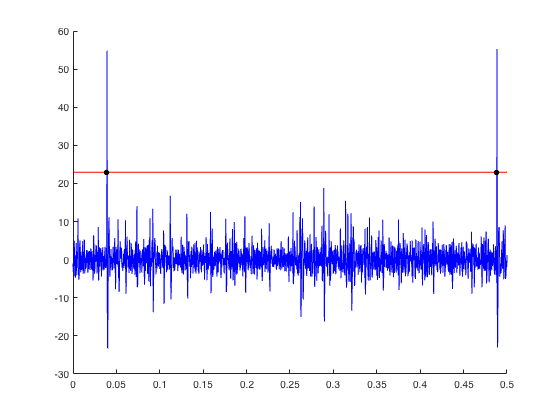

windowidth = 0.50; % Set this higher or lower if there are too few or too many spikes in the plot below.

% Chose your threshold with a single click on the filtered data
    figure("Visible", "on"); 
    plot(tim, vmfilt);
    xlim([0 1])
    title('Adjust, hit return, one Y click')
    pause;

    [~, thresh] = ginput(1);
    close(gcf);

% create an empty vector of the length of the data
    Z = zeros(1, length(vmfilt));
% Make every point where the data is above threshold equal to 1 and leave
% everything else as zero
    Z(vmfilt > thresh) = 1;

% Positive zero crossings will have a diff equal to 1   
    indices = find(diff(Z) == 1);

% Convert to seconds
    spiketimes = indices * VmdT;
    meanSpikeRate = 1 / mean(diff(spiketimes));

% and plot
figure; hold on;
    plot(tim, vmfilt, 'b');
    plot([0, windowidth], [thresh, thresh], 'r-');

    dts = thresh * ones(1,length(spiketimes));
    plot(spiketimes, dts, 'k.', 'MarkerSize', 16);
    xlim([0 windowidth]);

## Characterize baseline activity

Now that you have the spike times (either from the above code or from Spike2), you can characterize the baseline activity of these receptors (i.e., the spiking activity without stimulation). To do this we 1) calculate the mean baseline firing rate, 2) determine the interspike interval, 3) compute the coeffiecient of variation, 4) plot the phase distribution relative to the EOD, and 5) measure the degree of phase locking of the spike times releative to the EOD.

### 1. Baseline activity - no stimulus

% Take data before the first stimulus starts - marker(1) - or first 20
% seconds (whichever is longer)

    startspon = max([marker(1), 20]);
   
    spiketimesBaseLine = spiketimes(spiketimes < startspon); 

    % Calculate mean baseline firing rate (this varies wildly across neurons)
    meanBaseLinefiringrate = length(spiketimesBaseLine) / max(spiketimesBaseLine);  % Number of spikes divided by time
    fprintf(['Mean baseline firing rate of the neuron is: ' num2str(meanBaseLinefiringrate) ' Hz. \n'])

Mean baseline firing rate of the neuron is: 6.0417 Hz. 


    isi = diff(spiketimesBaseLine);

    % Compute the coefficient of variation (CV)
    standard_deviation_isi = std(isi);
    mean_isi = mean(isi);

% Definition of CV
    CV = standard_deviation_isi / mean_isi;

    fprintf('Mean ISI (ms): %3.2f CV: %3.2f \n', mean_isi*1000, CV)

Mean ISI (ms): 166.10 CV: 1.21 


### **2. Plot baseline interspike interval distribution (ISI Histogram) **

The temporal patterning of spikes, e.g. regular firing versus bursty, can be revealed in an ISI Histogram.

The histogram is sensitive to the firing rate of the neuron - if a neuron is firing around 100 Hz, the mean ISI will be around 10ms. Another neuron might fire at around 10Hz, and so its mean ISI will be around 100ms.  This is important in this visualization as you will need to adjust the **ISIrange** below to capture the patterns related to the neuron you are analyzing.

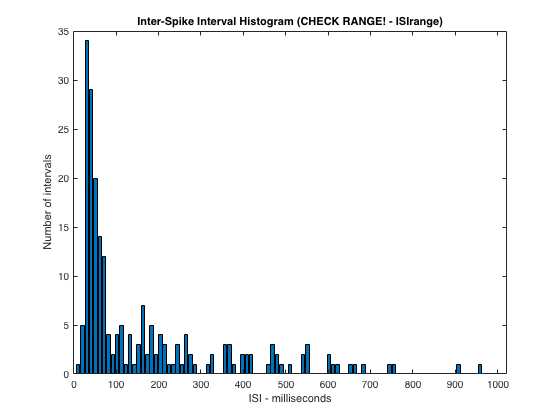

% Compute the ISI sequence - just use diff!
    isi = diff(spiketimesBaseLine); % ISI - times between spikes

% Make a histogram of ISIs - we need bins over the range of ISI durations
    ISIrange = [0.000, 0.010]; % CHOOSE WISELY! This will vary between neurons.
            % For phase locking afferents, [0, 0.010] is useful
            % For bursty neurons in the torus, [0, 2.000]

% Create 100 bins evenly distributed between the min and max of isi
    numbins = 100; % This is the number of bins (default 100)
    ISIbins = linspace(ISIrange(1), ISIrange(2), numbins); 
    % Make the histogram
    numbercounts = histcounts(isi, ISIbins); % Calculate the histogram

% Plot ISI histogram
    figure; box on; 
    bar(ISIbins(2:end)*1000, numbercounts);
    xlabel('ISI - milliseconds');
    ylabel('Number of intervals');
    title('Inter-Spike Interval Histogram (CHECK RANGE! - ISIrange)');

Describe the distribution. What processes could give rise to multimodal distributions?

### **3. Plot phase of spiking relative to the EOD (baseline)**

You might have noticed that receptor afferents tend to fire near a local maximum of the EOD. What about the pyramidal cells in the ELL or neurons in the torus? 

Here we evaluate the phase relationship between the spike train and the EOD. To do this, you’ll need to convert the spike times into phases with respect to the nearest EOD zero crossing.

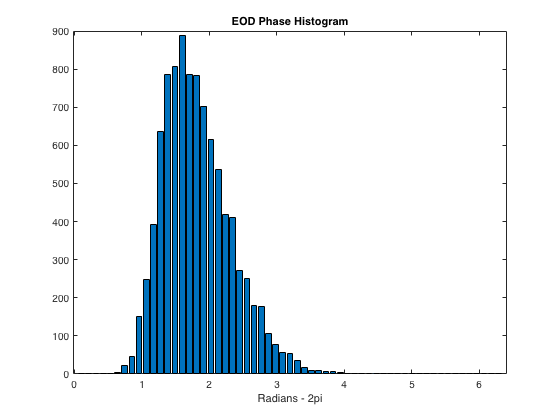

% Compute a phase histogram relative to the EOD. 
% Select the spike times between the 1st and last EOD zero-crossings of our
% sample before the first stimulus occurred - almost all spikes if not all!

spiketimesBaseEOD = spiketimesBaseLine(spiketimesBaseLine > EOD0Xings(1)...
    & spiketimesBaseLine < EOD0Xings(end));

% Created an empty vector length of the zerocrossings
      EODSpikephase = zeros(length(spiketimesBaseEOD), 1); % PreAllocate for speed

% Loop over the spiketimes
    for I = 1:length(spiketimesBaseEOD) % For each spike... 
        ind = find(EOD0Xings <= spiketimesBaseEOD(I), 1, 'last'); % Get previous EOD zero Xing
        % Phase is 2pi times the ratio [time from EOD crossing prior to spike] / [duration of the EOD crossing to the subseqent]     
        EODSpikephase(I) = 2 * pi * (spiketimesBaseEOD(I) - EOD0Xings(ind)) / (EOD0Xings(ind+1) - EOD0Xings(ind));
    end

% Plot phase distribution
    numbins = 60; % Number of bins for the histogram (60 is default)
    PhaseHistedges = linspace(0, 2*pi, numbins);
    PhaseHistbins = histcounts(EODSpikephase, PhaseHistedges);
    figure; hold on; box on;
    bar(PhaseHistedges(2:end), PhaseHistbins);
    xlabel('Radians - 2pi')
    title('EOD Phase Histogram')

### **4. Measure degree of phase locking (vector strength) to EOD**

Vector strength is used as a measure of phase locking (commonly used for analysis of the auditory system) and ranges between zero and one.

% Compute the vector strength (VS)
    vector_strength = sqrt(mean(cos(EODSpikephase)).^2 + mean(sin(EODSpikephase)).^2);
    disp(['VS: ' num2str(vector_strength)])

VS: 0.88602
